## Week 8 Workshop: Plotting fixation densities

In Week 5, we plotted eye traces from individual trials over example images. Today, we're going to try to get a sense of how consistent we looked at the same image across trials. We can also start comparing this to other subjects in our group. To do this, we're going to plot a 2 dimensional histogram, looking at the joint probability of looking at any given x and y coordinate on the image at a given point in time. In order to overaly the histogram on top of images, we'll have to do a conversion from dov to pixels like we did in week 5. Another consideration will be comparing images between subjects. Since every subject was shown images in a random order, we'll have to use the file names to match up images across subjects.

First, let's load up the data for the subjects in our group and assign colors to each like we did last week:

% list of subjects
subjects = {'rr', 'ae'}; % edit this cell array to include the members of your group!

% assign a color for each subject
subject_colors = {'#ca0020','#0571b0'}; % HEX values, could also be RGB triplets

for i = 1:numel(subjects) % loop through each subject
    subject = subjects{i};
    filename = [subject '.utimages.export.mat'];
    load(filename)
    
    teamdata.(subject) = data.(subject);
    clear data
end

And now we can start analysing!

### Plotting a two dimensional histogram

First, as a starting point, let's work with the same example image we used in week 5. In your stucture variable, there should be a variable that contains the filenames for each image: `teamdata.(subject).imgkey`. The image we used as an exmpample in week 5 was `'cps201410017283'`. Let's start by finding all the trial numbers where this image was shown for each subject:

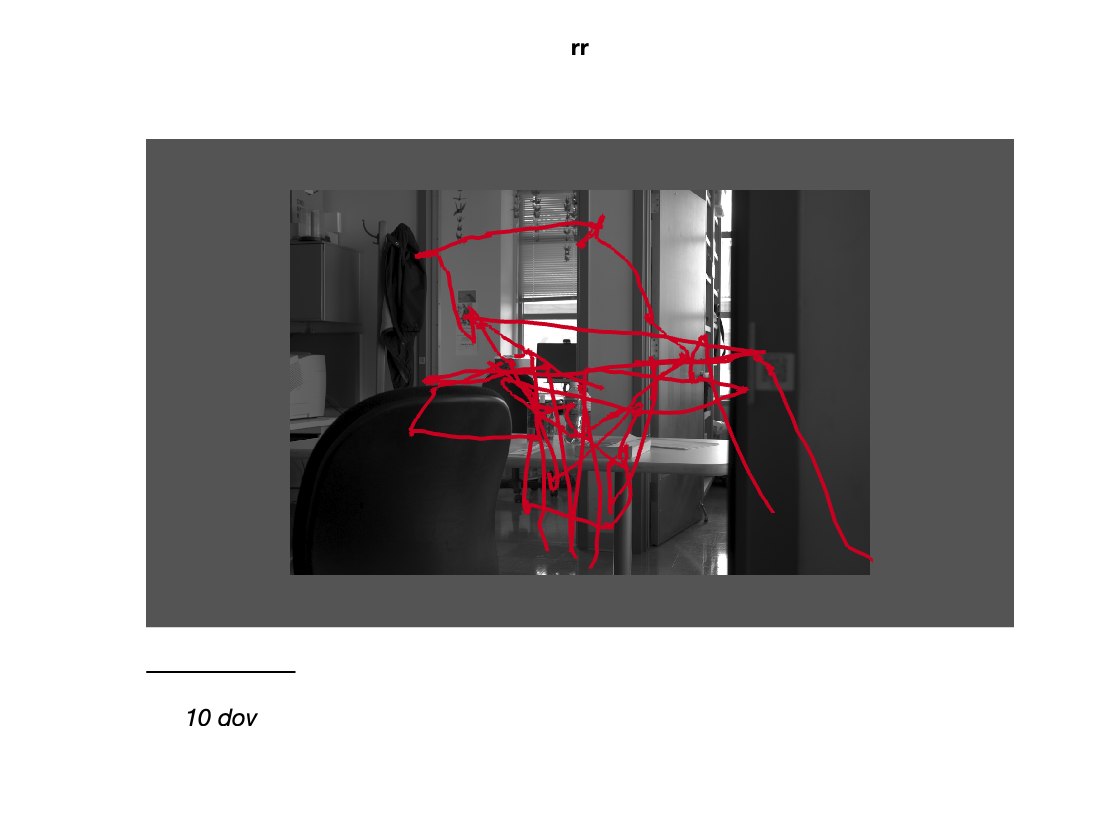

hdata = struct with fields:
    rr: [1×1 Histogram2]
    ae: [1×1 Histogram2]


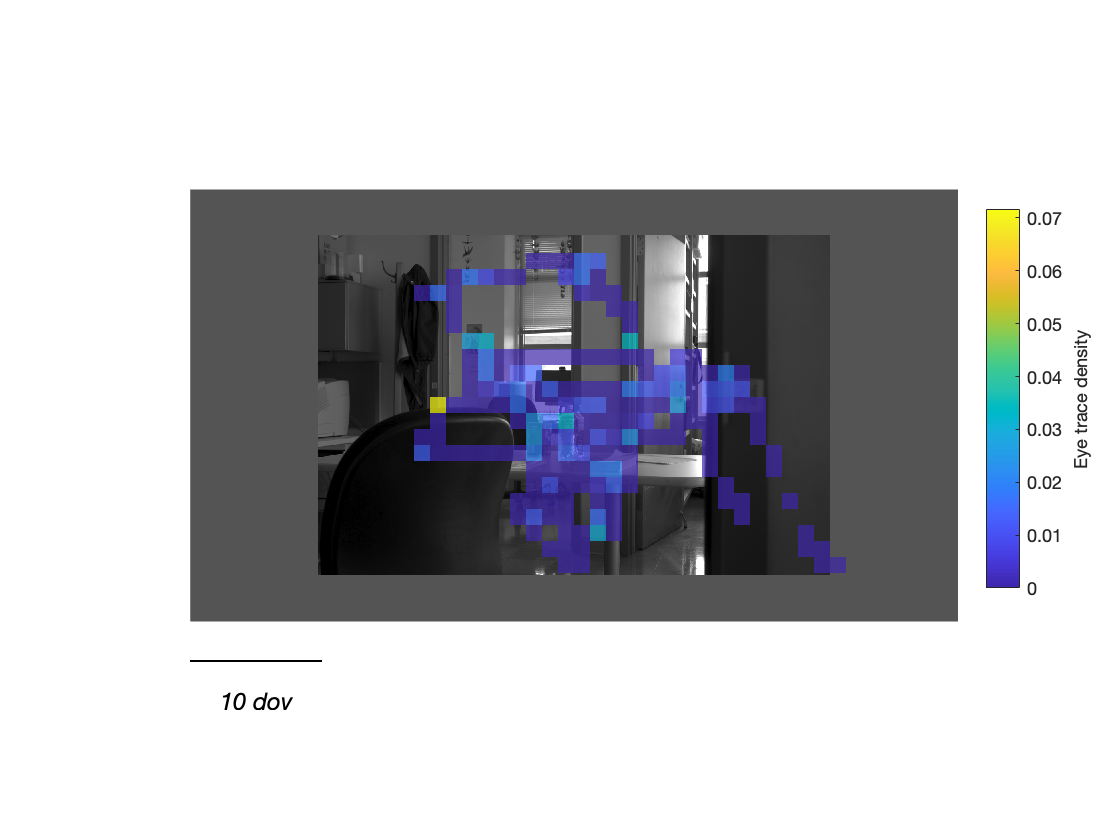

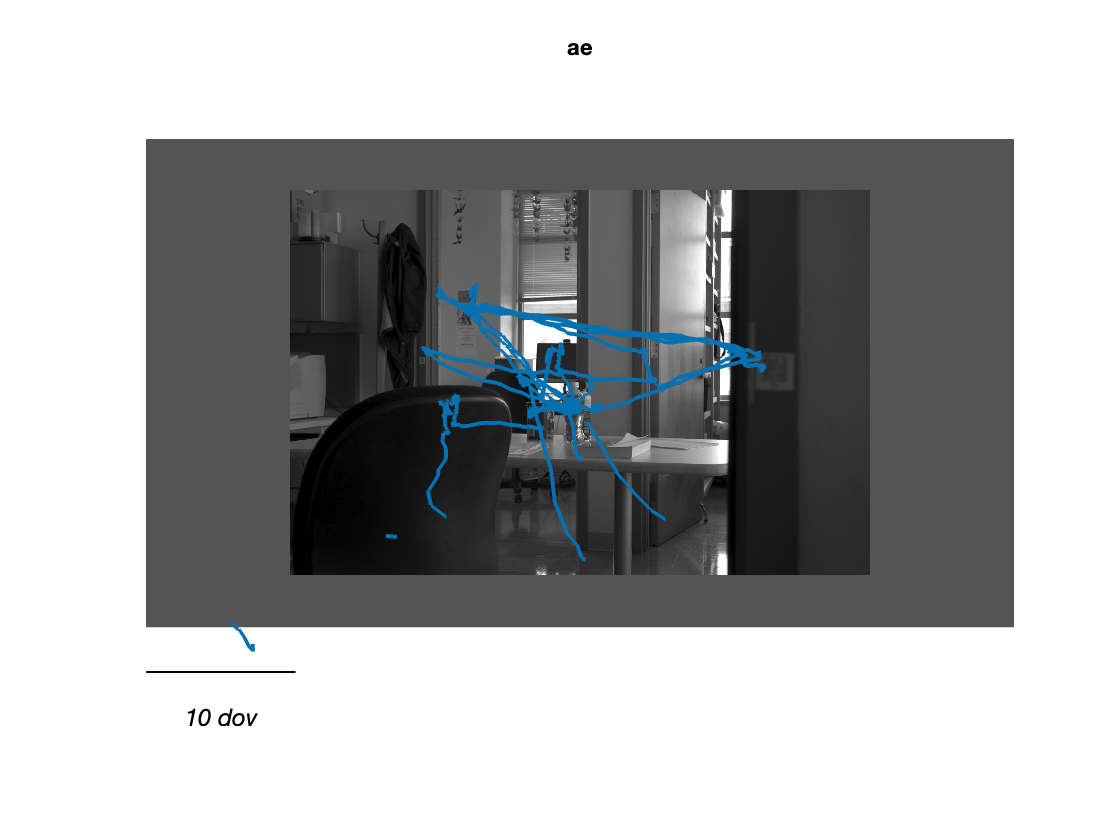

hdata = struct with fields:
    rr: [1×1 Histogram2]
    ae: [1×1 Histogram2]


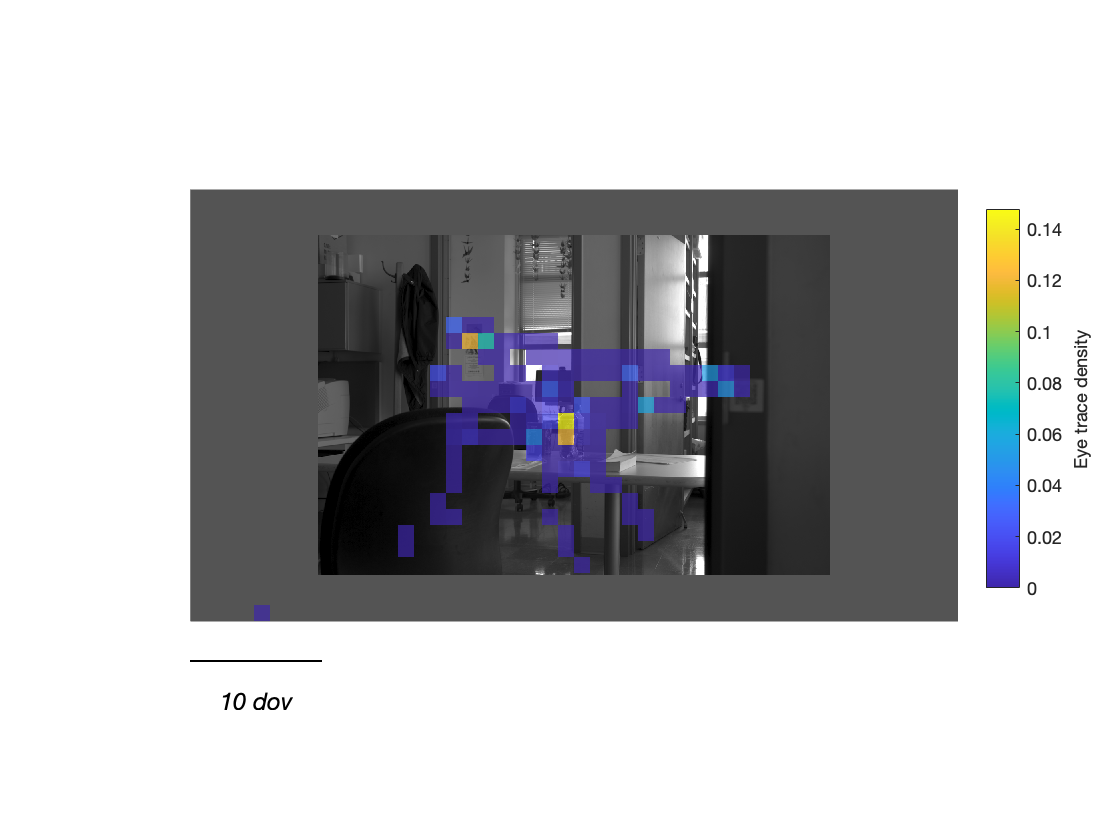

imgstr =  'cps201410017283'; % change this to look at different images
% NOTE: because images are shown randomly, its possilbe not every subject
% saw every image. We'll optimise for which images are best for your group
% in the next section.

for i = 1:numel(subjects) % loop through each subject
    subject = subjects{i};
    
    % we'll need these from week 5:
    width = teamdata.(subject).screeninfo.dov_width; % width of the screen in degrees of visual angle
    pixelsperdeg = teamdata.(subject).screeninfo.xpixels/width;
    pixelxzero = teamdata.(subject).screeninfo.xpixels/2; % find the center of the screen x coordinate
    pixelyzero = teamdata.(subject).screeninfo.ypixels/2; % find the center of the screen y coordinate

    % find all the trials that image was shown:
    trind = find(strcmp(teamdata.(subject).imgkey,imgstr));
    
    % let's first convert the x and y traces on these trials to pixels, and
    % then plot them over the image:
    xtrace = teamdata.(subject).eyetrace.X(trind,:) .* pixelsperdeg + pixelxzero;
    ytrace = teamdata.(subject).eyetrace.Y(trind,:) .* -pixelsperdeg + pixelyzero;
    
    % get the image
    imgind = teamdata.(subject).image_index(trind(1));
    img = squeeze(teamdata.(subject).images(imgind,:,:));

    figure;

    imagesc(img)
    colormap('gray')
    hold on;

    plot(xtrace',ytrace','-', 'Color', subject_colors{i},'LineWidth',2) % you can also specifiy color with hex values!
    scalebar = pixelsperdeg*10;
    line([1 scalebar], [teamdata.(subject).screeninfo.ypixels+100 teamdata.(subject).screeninfo.ypixels+100],'Color',[0 0 0],'Linewidth',1)
    text(mean([1 scalebar]), teamdata.(subject).screeninfo.ypixels+200,'10 dov','FontName','Helvetica', 'FontAngle','italic','FontSize',12,'HorizontalAlignment','center');
    title(subject)
    axis equal
    axis off
    
    % now let's convert those x and y positions into a 2D histogram
    figure; 
    % plot image
    ax1 = axes;
    imagesc(img)
    axis equal 
    
    % plot histogram
    ax2 = axes;
    
    binsize = 40; % size of bins in pixels
    hdata.(subject) = histogram2(xtrace,ytrace,'DisplayStyle','tile','XBinEdges',0:binsize:teamdata.(subject).screeninfo.xpixels,'YBinEdges',0:binsize:teamdata.(subject).screeninfo.ypixels,'Normalization','probability','EdgeColor','none','FaceAlpha',0.7)
    axis equal 
    
    linkaxes([ax1,ax2])
    
    ax1.Visible = 'off';
    ax2.Visible = 'off';
    
    ax2.YDir = 'reverse';

    colormap(ax1,'gray')
    colormap(ax2,'parula')

    set([ax1,ax2],'Position',[.17 .11 .685 .815]);
    cb2 = colorbar(ax2,'Position',[.88 .3 .03 .45]);
    cb2.Label.String = 'Eye trace density';
    
    scalebar = pixelsperdeg*10;
    line([1 scalebar], [teamdata.(subject).screeninfo.ypixels+100 teamdata.(subject).screeninfo.ypixels+100],'Color',[0 0 0],'Linewidth',1)
    text(mean([1 scalebar]), teamdata.(subject).screeninfo.ypixels+200,'10 dov','FontName','Helvetica', 'FontAngle','italic','FontSize',12,'HorizontalAlignment','center');
    
    
end

### Finding the best images for your group's analysis

190+ images is a lot, it would be useful to pick a few images to use as examples for the plots we made in week 5 and these plots. But which are the best images for your group? The image above may not be the best for your group, some participants may have only 1 or 2 trials. Let's choose a subset of 50 images for our analyses. Find 50 images that were seen by all members of your group: 

% get the unique string of images seen by each subject

for i = 1:numel(subjects) 
    subject = subjects{i};
    imglist.(subject) = unique(teamdata.(subject).imgkey);
    imglist.(subject) = sort(imglist.(subject)); % put them in alphabetical order
end

imglist.all = intersect(imglist.rr, imglist.ae);

% to do this with a group of four subjects, we can nest calls to intersect
% like this:
%imglist.all = intersect(imglist.subject1, intersect(imglist.subject2,intersect(imglist.subject3,imglist.subject4)));

grpimglist = imglist.all(1:50); 
% Note: 50 is sort of randomly chosen for managability. feeling fancy? use all of imglist.all!


### Measuring the differences across subjects

Now we want to put everything we've learned together. We want to know how different fixations patterns are across subjects. A simple way to do this is to calculate the difference in the fixation density maps that we caluclated above. We saved the `histogram2` data into a variable called `hdata `so we can easily calculate this for the example image:

fixdiff = abs(hdata.(subjects{1}).Values' - hdata.(subjects{2}).Values');
fixXaxis = hdata.(subjects{1}).XBinEdges(1)+binsize/2:binsize:hdata.(subjects{1}).XBinEdges(end); % get bin centers in pixels
fixYaxis = hdata.(subjects{1}).YBinEdges(1)+binsize/2:binsize:hdata.(subjects{1}).YBinEdges(end); % get bin centers in pixels
% let's visualize this over the image:
figure;
% plot image
ax1 = axes;
imagesc(img)
axis equal

% plot difference
ax2 = axes;
h = imagesc(fixXaxis,fixYaxis,fixdiff)

h =   Image with properties:

           CData: [27×48 double]
    CDataMapping: 'scaled'

  Show all properties


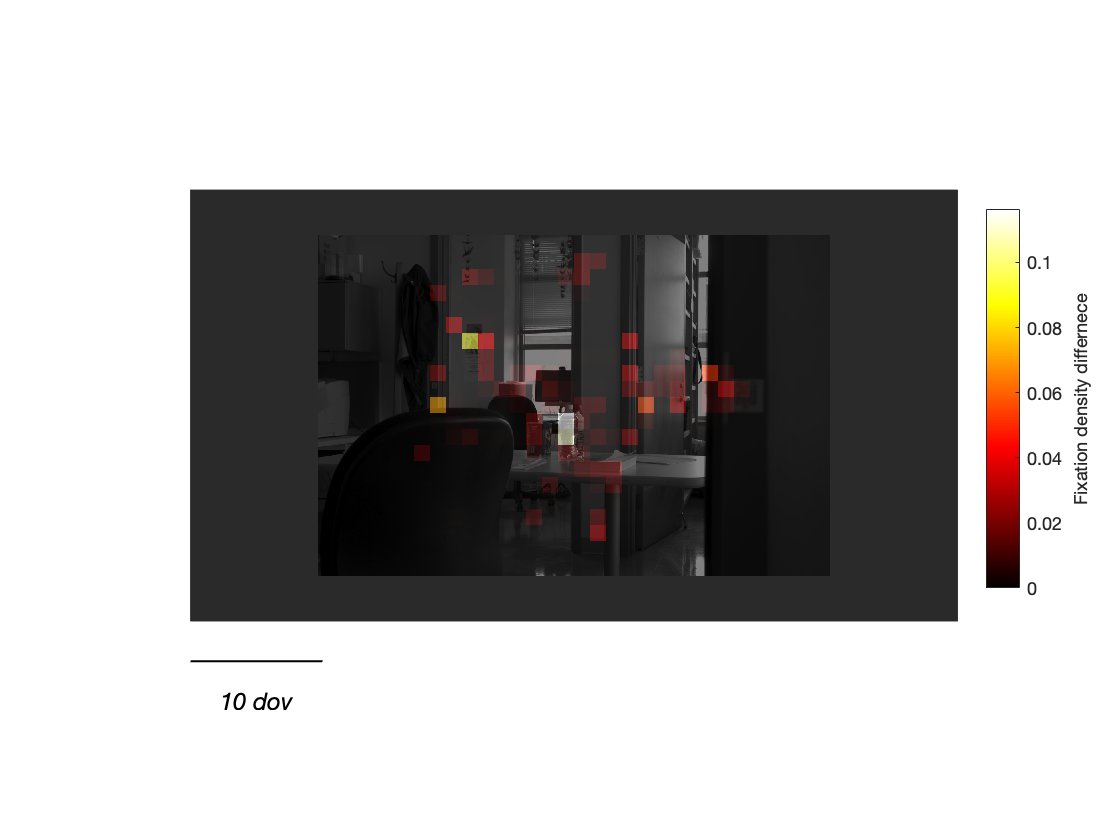

set(h,'AlphaData',0.5)
axis equal

linkaxes([ax1,ax2])

ax1.Visible = 'off';
ax2.Visible = 'off';

% ax2.YDir = 'reverse';

colormap(ax1,'gray')
colormap(ax2,'hot') % using a different color scale here

set([ax1,ax2],'Position',[.17 .11 .685 .815]);
cb2 = colorbar(ax2,'Position',[.88 .3 .03 .45]);
cb2.Label.String = 'Fixation density differnece';

scalebar = pixelsperdeg*10;
line([1 scalebar], [teamdata.(subject).screeninfo.ypixels+100 teamdata.(subject).screeninfo.ypixels+100],'Color',[0 0 0],'Linewidth',1)
text(mean([1 scalebar]), teamdata.(subject).screeninfo.ypixels+200,'10 dov','FontName','Helvetica', 'FontAngle','italic','FontSize',12,'HorizontalAlignment','center');



% now we can quantify this with mean and standard deviation:
disp(['mean fixation difference = ' num2str(mean(fixdiff(:)))])

mean fixation difference = 0.0011203


disp(['std fixation difference = ' num2str(std(fixdiff(:)))])

std fixation difference = 0.0068099


Now, let's loop through the 50 objects we've selected and see how they compare across subjects. This will let us answer two interesting questions:

- Which images were viewed the most similarly? Which images were the most different?

- Which subjects were the most alike? Which subjects were the most different?

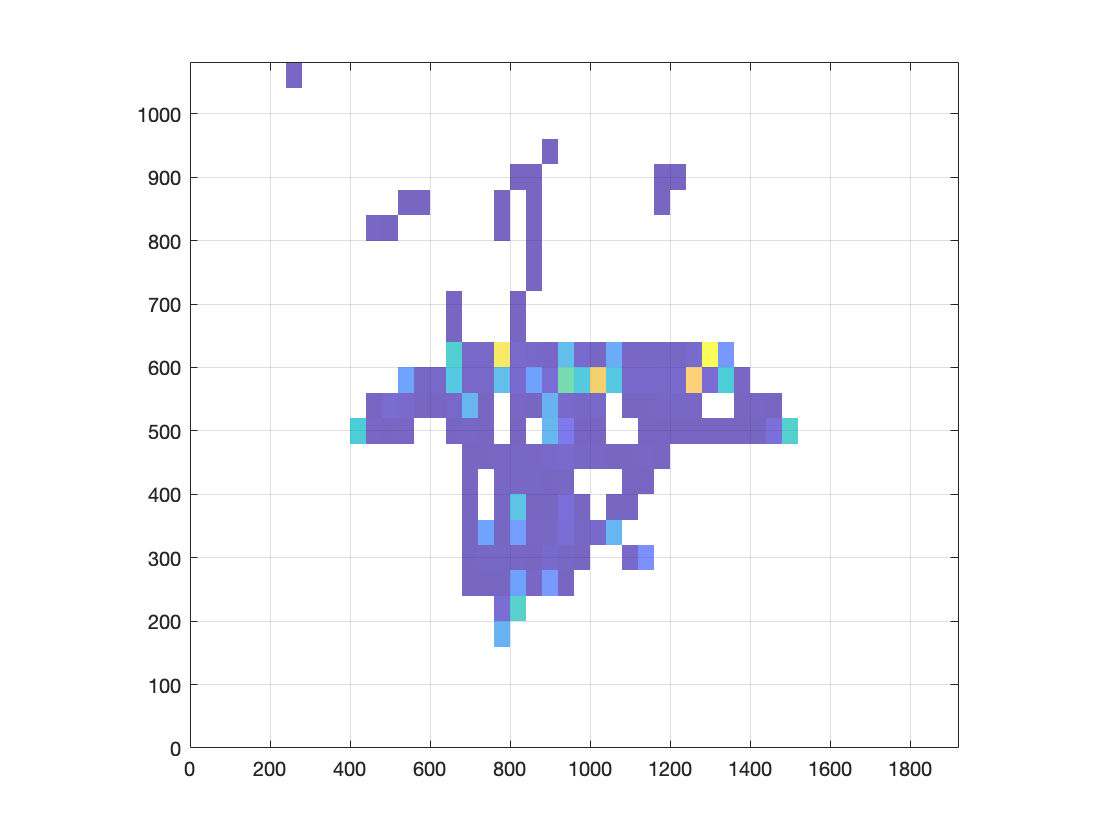

% first let's figure out how many paris of subjects are in your group:
pairs = nchoosek(1:numel(subjects),2); 
% my example is boring since i only have one pair, but a group of 4 should
% have 6 unique pairs.

% for each pair, calculate the differences across images. for efficiency,
% let's preallocate a martrix (this helps matalb go faster):
meandiffmatrix = nan(size(pairs,1),numel(grpimglist)); % each row is a subject pair, each column is a different image
stddiffmatrix = nan(size(pairs,1),numel(grpimglist)); % each row is a subject pair, each column is a different image

% loop through subject pairs
for i = 1:size(pairs,1)
    subject1 = subjects{pairs(i,1)};
    subject2 = subjects{pairs(i,2)};
    
    % loop through images
    for j = 1:numel(grpimglist)
        imgstr =  grpimglist{j};
        
        % get data for subject 1
        width = teamdata.(subject1).screeninfo.dov_width; % width of the screen in degrees of visual angle
        pixelsperdeg = teamdata.(subject1).screeninfo.xpixels/width;
        pixelxzero = teamdata.(subject1).screeninfo.xpixels/2; % find the center of the screen x coordinate
        pixelyzero = teamdata.(subject1).screeninfo.ypixels/2; % find the center of the screen y coordinate

        % find all the trials that image was shown:
        trind = find(strcmp(teamdata.(subject1).imgkey,imgstr));
    
        xtrace = teamdata.(subject1).eyetrace.X(trind,:) .* pixelsperdeg + pixelxzero;
        ytrace = teamdata.(subject1).eyetrace.Y(trind,:) .* -pixelsperdeg + pixelyzero;
        
        htmp = histogram2(xtrace,ytrace,'DisplayStyle','tile','XBinEdges',0:binsize:teamdata.(subject1).screeninfo.xpixels,'YBinEdges',0:binsize:teamdata.(subject1).screeninfo.ypixels,'Normalization','probability','EdgeColor','none','FaceAlpha',0.7);
        
        subject1fixdata = htmp.Values;
        
        % get data for subject 2
        width = teamdata.(subject2).screeninfo.dov_width; % width of the screen in degrees of visual angle
        pixelsperdeg = teamdata.(subject2).screeninfo.xpixels/width;
        pixelxzero = teamdata.(subject2).screeninfo.xpixels/2; % find the center of the screen x coordinate
        pixelyzero = teamdata.(subject2).screeninfo.ypixels/2; % find the center of the screen y coordinate

        % find all the trials that image was shown:
        trind = find(strcmp(teamdata.(subject2).imgkey,imgstr));
    
        xtrace = teamdata.(subject2).eyetrace.X(trind,:) .* pixelsperdeg + pixelxzero;
        ytrace = teamdata.(subject2).eyetrace.Y(trind,:) .* -pixelsperdeg + pixelyzero;
        
        htmp = histogram2(xtrace,ytrace,'DisplayStyle','tile','XBinEdges',0:binsize:teamdata.(subject2).screeninfo.xpixels,'YBinEdges',0:binsize:teamdata.(subject2).screeninfo.ypixels,'Normalization','probability','EdgeColor','none','FaceAlpha',0.7);
        
        subject2fixdata = htmp.Values;
        
        % calcualte mean difference
        fixdiff = abs(subject1fixdata - subject2fixdata);
        
        meandiffmatrix(i,j) = mean(fixdiff(:));
        stddiffmatrix(i,j) = std(fixdiff(:));
        
    end
    
end

Now let's plot the data! Below we're going to explore a few ways to plot the data. But there are infinite ways to visualize it. See if your group can come up with some extra ideas.

First, let's see which images had the smallest fixation differences and which had the greatest across subject pairs. 

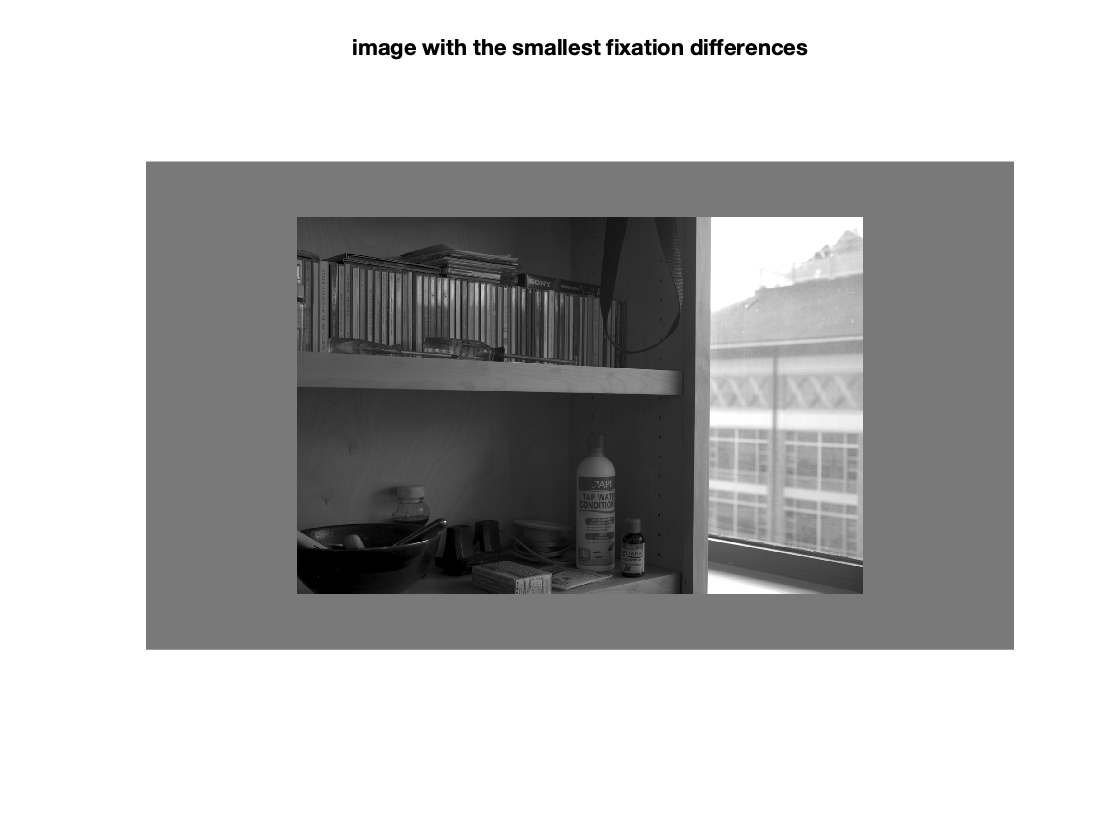

% average the matrix across subjects:
aveacrosssubjects = mean(meandiffmatrix,1);
[imagessortedbydiff, imgdiffindex] = sort(aveacrosssubjects,'ascend'); % sort from smallest to largest difference

% here's the image that had the smallest fixation differences in your
% group:
imgstr = grpimglist{imgdiffindex(1)};
trind = find(strcmp(teamdata.(subjects{1}).imgkey,imgstr));
imgind = teamdata.(subjects{1}).image_index(trind(1));
img = squeeze(teamdata.(subjects{1}).images(imgind,:,:));

figure;
imagesc(img)
colormap('gray')
title('image with the smallest fixation differences')
axis equal
axis off

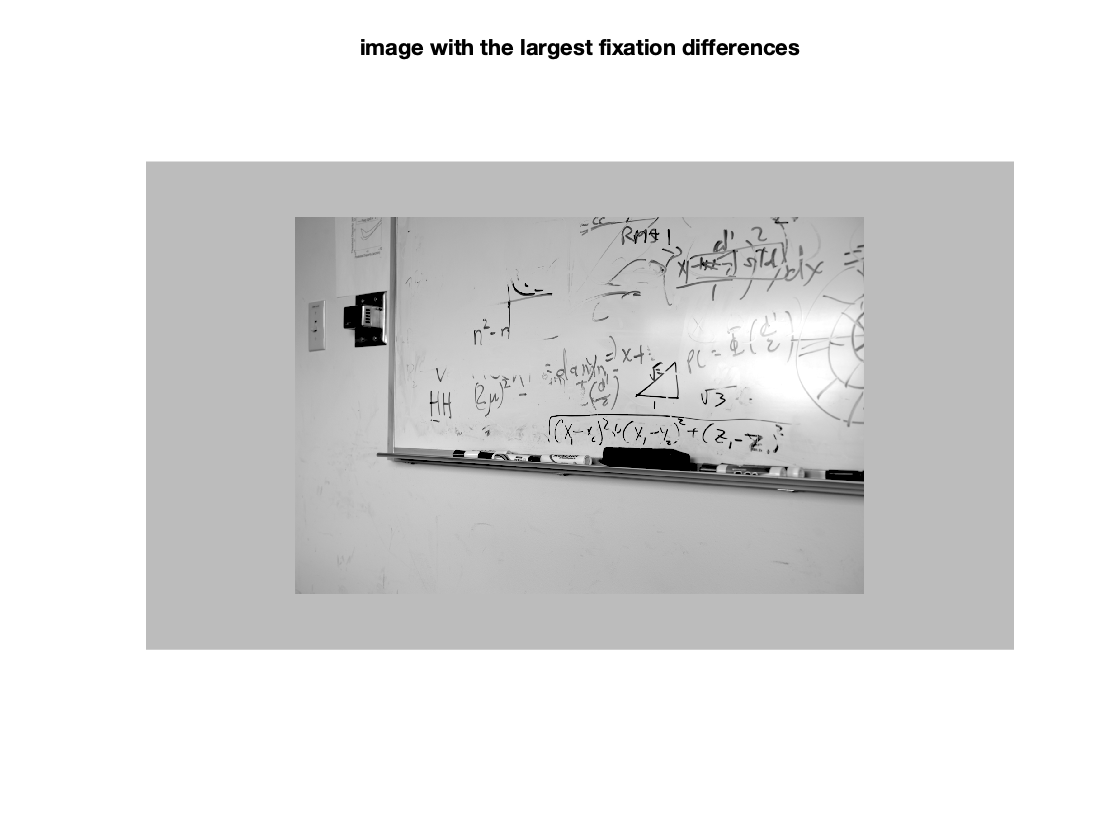


% and here's the one with the biggest fixation differences:
imgstr = grpimglist{imgdiffindex(end)};
trind = find(strcmp(teamdata.(subjects{1}).imgkey,imgstr));
imgind = teamdata.(subjects{1}).image_index(trind(1));
img = squeeze(teamdata.(subjects{1}).images(imgind,:,:));

figure;
imagesc(img)
colormap('gray')
title('image with the largest fixation differences')
axis equal
axis off


% we can do the same comparisons across subject pairs:
aveacrossimages = mean(meandiffmatrix,2);
[pairssortedbydiff, pairdiffindex] = sort(aveacrossimages,'ascend'); % sort from smallest to largest difference

disp([subjects{pairs(pairdiffindex(1),1)} ' and ' subjects{pairs(pairdiffindex(1),2)} ' had the  most similar fixation patterns'])

rr and ae had the  most similar fixation patterns


disp([subjects{pairs(pairdiffindex(end),1)} ' and ' subjects{pairs(pairdiffindex(end),2)} ' had the  least similar fixation patterns'])

rr and ae had the  least similar fixation patterns


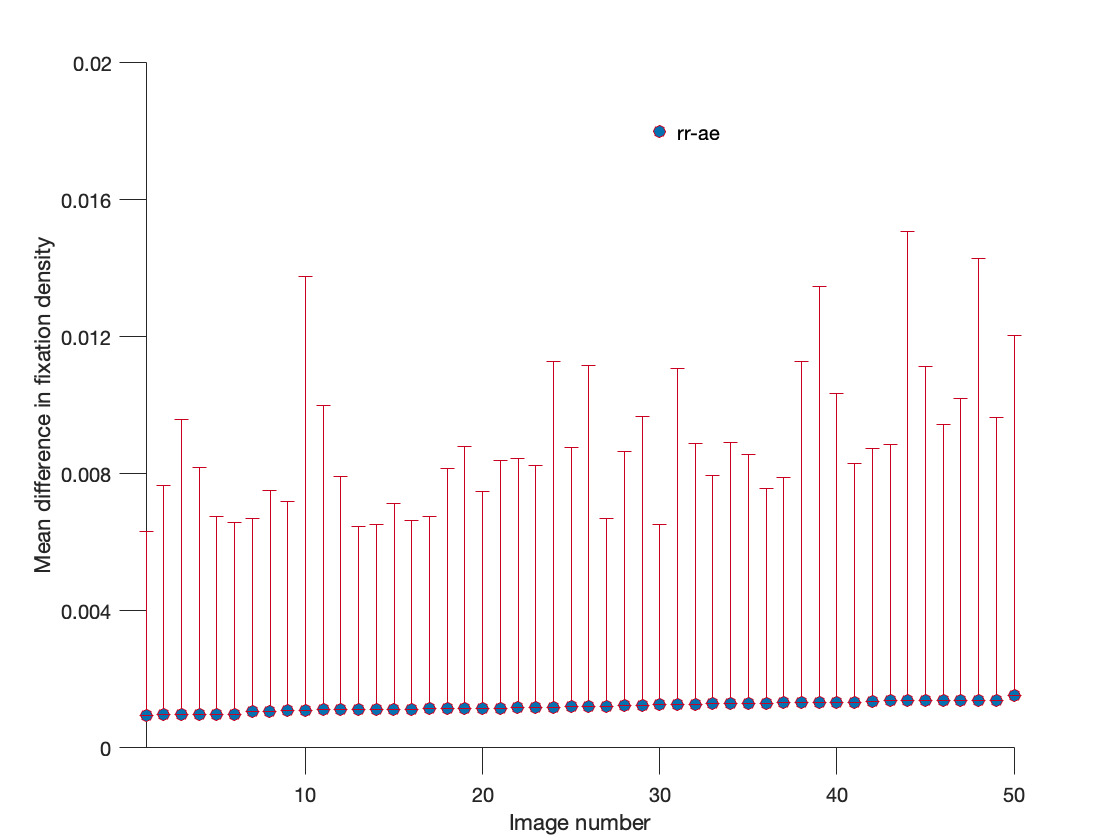


% now let's plot some quanitative graphs
% first, let's try it as a line graph across subject pairs:

figure;
hold on;

for i = 1:size(pairs,1)
 
    errorbar(1:numel(grpimglist), meandiffmatrix(i,imgdiffindex), zeros(1,numel(grpimglist)), stddiffmatrix(i,imgdiffindex),'o','Color',subject_colors{pairs(i,1)},'MarkerFaceColor',subject_colors{pairs(i,2)})
    
    % legend'
    plot(30,0.02-(0.002*i),'o','Color',subject_colors{pairs(i,1)},'MarkerFaceColor',subject_colors{pairs(i,2)})
    text(31,0.02-(0.002*i),[subjects{pairs(i,1)} '-' subjects{pairs(i,2)}], 'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
end

% make axes look neat
set(gca,'XTick', 0:numel(grpimglist)/5:numel(grpimglist));
set(gca,'YTick',  0:.004:0.02);
set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
set(gca,'TickDir', 'out');
set(gca,'TickLength', [0.03,0.035]);
xlabel('Image number')
ylabel('Mean difference in fixation density')
axis([1 numel(grpimglist) 0 0.02])
box off

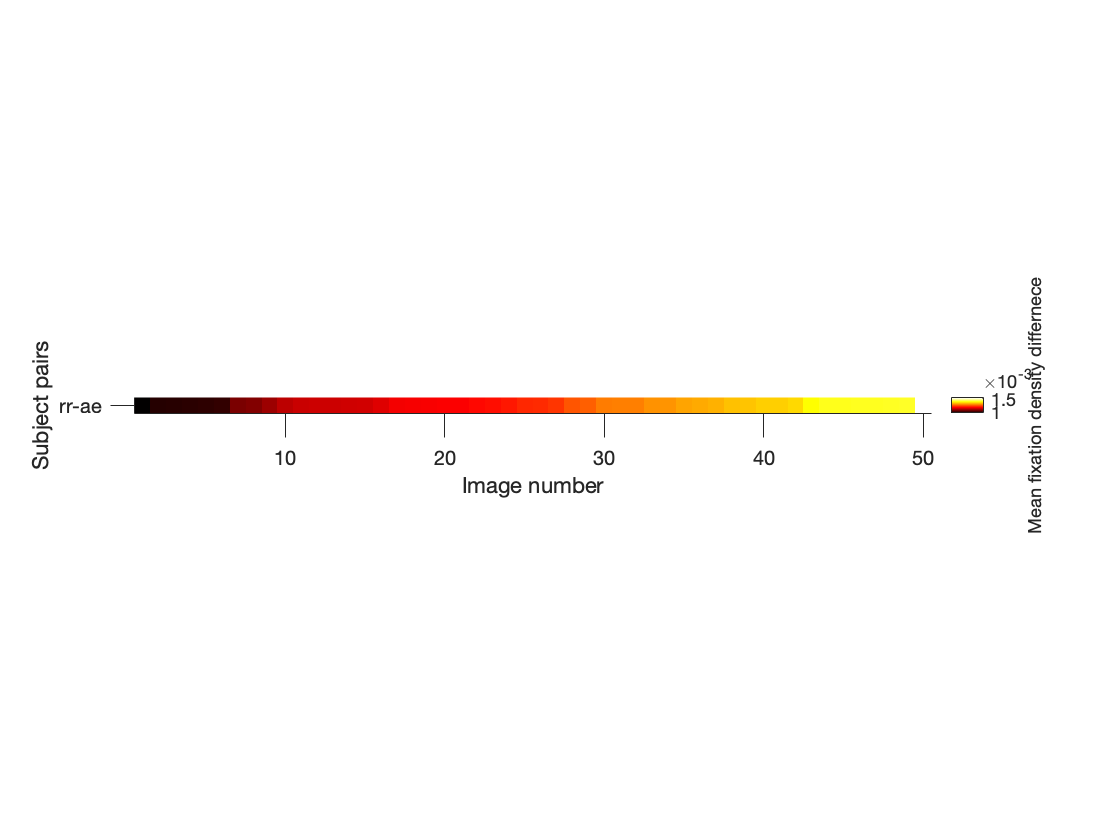


% let's plot the whole matrix, sorted as above:

figure;

% first the matrix:
imagesc(meandiffmatrix(pairdiffindex,imgdiffindex))
colormap('hot')
c = colorbar('Eastoutside');

% c = colorbar('Position',[.88 .3 .03 .45]);
c.Label.String = 'Mean fixation density differnece';
% make a string to label the y axes
ystr = cell(1,size(pairs,1));
for i = 1:size(pairs,1)
    ystr{i} = [subjects{pairs(pairdiffindex(i),1)} '-' subjects{pairs(pairdiffindex(i),2)}];
end

set(gca,'XTick', 0:numel(grpimglist)/5:numel(grpimglist));
set(gca,'YTick',  1:1:size(pairs,1),'YTickLabel',ystr);
set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
set(gca,'TickDir', 'out');
set(gca,'TickLength', [0.03,0.035]);
xlabel('Image number')
ylabel('Subject pairs')
axis equal
axis tight
box off

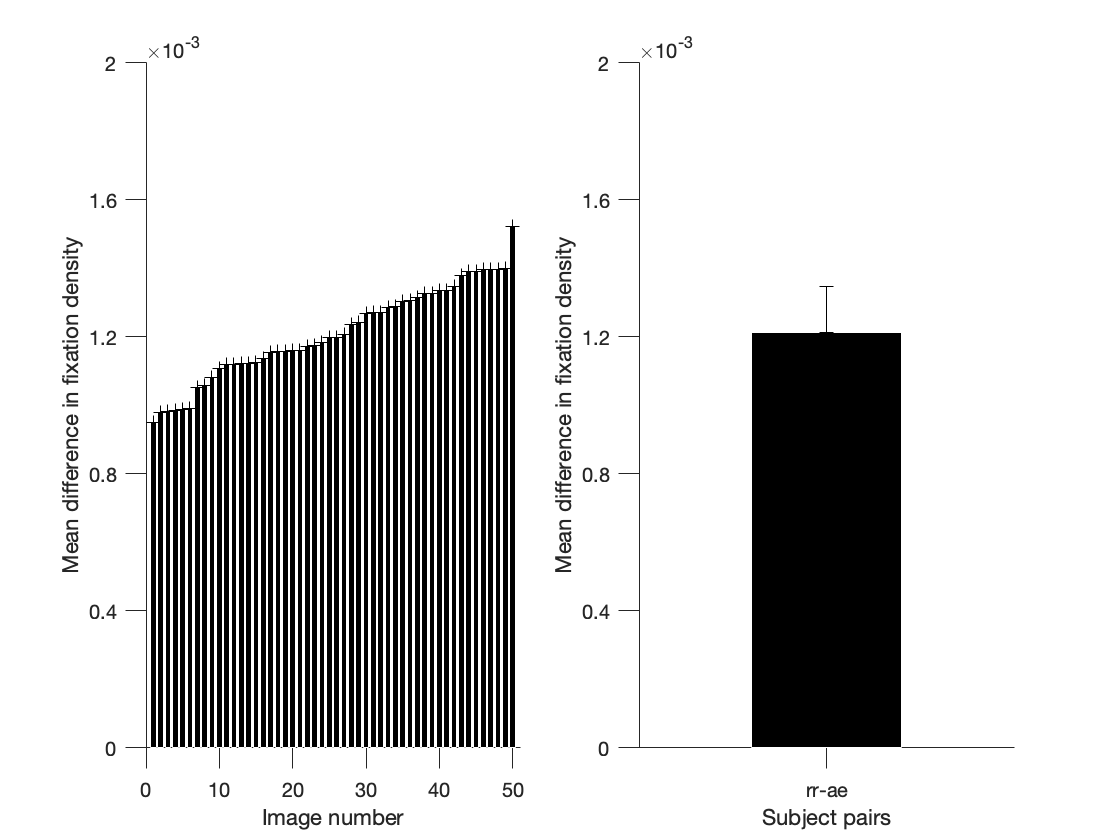


% and some bar graphs of the sorted matrix:
figure;
subplot(1,2,1)
hold on;
bar(1:numel(grpimglist), mean(meandiffmatrix(pairdiffindex,imgdiffindex),1),'FaceColor',[0 0 0],'EdgeColor',[1 1 1])
errorbar(1:numel(grpimglist), mean(meandiffmatrix(pairdiffindex,imgdiffindex),1),std(meandiffmatrix(pairdiffindex,imgdiffindex),0,1),'+','Color',[0 0 0])

set(gca,'XTick', 0:numel(grpimglist)/5:numel(grpimglist));
set(gca,'YTick',  (0:.4:2)*10^-3);
set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
set(gca,'TickDir', 'out');
set(gca,'TickLength', [0.03,0.035]);
xlabel('Image number')
ylabel('Mean difference in fixation density')
axis([0 numel(grpimglist)+1 0 2*10^-3])
box off


% add a bar graph to the right:
subplot(1,2,2),
hold on;
bar(1:size(pairs,1), mean(meandiffmatrix(pairdiffindex,imgdiffindex),2),'FaceColor',[0 0 0],'EdgeColor',[1 1 1])
errorbar(1:size(pairs,1), mean(meandiffmatrix(pairdiffindex,imgdiffindex),2), std(meandiffmatrix(pairdiffindex,imgdiffindex),0,2),'+','Color',[0 0 0])

set(gca,'XTick',1:1:size(pairs,1),'XTickLabel',ystr);
set(gca,'YTick',  (0:.4:2)*10^-3);
set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
set(gca,'TickDir', 'out');
set(gca,'TickLength', [0.03,0.035]);
xlabel('Subject pairs')
ylabel('Mean difference in fixation density')
axis([0 size(pairs,1)+1 0 2*10^-3])
box off

### Exercises

Now its time to start thinking about putting our posters together. 

Its probably a good time to sit down as a group and write down an outline of what figures you want to go in your posters. What results do you want to include? Are there any additional plots/statistics tests that we havent covered?

You'll also want to come up with some conclusions. Based on your data, are there features of the images that are driving differences in fixation similarities/differences? If you plot the 5 or 10 most similar/different images from your group - are there noticable features of those images that might be driving the differences?

What examples images do you want to include? You could use one we've alreaady talked about or a favourite. 